syms x(t) y(t) z(t) omegar(t) omegaf(t)
syms Y
phi = (60*pi/180);
sideslipang = 15*pi/180; %keep it less than max
format long
l1=1.1;l2=0.8; 
alpha1=75*pi\180;alpha2=75*pi\180;
daero=0.28; %aero damping coeff
ksr=92000;ksf=84400; % lateral stiffnesses of tires
Rr=0.317;Rf=0.292; % rolling radius rear and front
tr=0.097;tf=0.062; % radius of cross section rear and front
Ir=0.66;If=0.47; % Moment of inertia tires
g=9.8;
Ma=223; % rear frame mass including rider
Mb=10.0; % swingarm mass 
Mc=7.0; % front unsprung mass
Md=16.2; % rear wheel mass
Mg=12.0; % front wheel mass
Mf=8.75; % steering column mass
M = Ma+Mb+Mc+Md+Mf+Mg;

% b-entire body same as tires too
% m-ground
syms cb db bm [3 3]

cb(1,1)=cos(alpha1);cb(1,2)=-sin(alpha1);cb(1,3)=0;
cb(2,1)=sin(alpha1);cb(2,2)=cos(alpha1);cb(2,3)=0;
cb(3,1)=0;cb(3,2)=0;cb(3,3)=1;

db(1,1)=cos(alpha2);db(1,2)=sin(alpha2);db(1,3)=0;
db(2,1)=-sin(alpha2);db(2,2)=cos(alpha2);db(2,3)=0;
db(3,1)=0;db(3,2)=0;db(3,3)=1;

bm(1,1)=1;bm(1,2)=0;bm(1,3)=0;
bm(2,1)=0;bm(2,2)=cos(phi);bm(2,3)=sin(phi);
bm(3,1)=0;bm(3,2)=-sin(phi);bm(3,3)=cos(phi);

bc=simplify(inv(cb));bd=simplify(inv(db));mb=simplify(inv(bm));

syms B F R [1 3] %#ok<NASGU> 

B(1)=x;B(2)=y;B(3)=z;
Bx=B(1);By=B(2);Bz=B(3);
F = B + [l1 0 0]*mb*bc;
Fx=F(1);Fy=F(2);Fz=F(3);
R = B - [l2 0 0]*mb*bd;
Rx=R(1);Ry=R(2);Rz=R(3);

syms Cr Cf [1 3] %#ok<NASGU> 

Cr = R + [0 -Rr*cos(phi) Rr*sin(phi)]*mb;
Crx=Cr(1);Cry=Cr(2);Crz=Cr(3);
Cf = F + [0 -Rf*cos(phi) Rf*sin(phi)]*mb;
Cfx=Cf(1);Cfy=Cf(2);Cfz=Cf(3);

fw=0.02; %rolling resistance coeff
maxsideslip=16*pi/180;
maxpneumatictrail=0.03;

% some more geometry parameters
b = Bx - Crx;
b = vpa(b)

$$b = 0.57769077049273229758105894598119$$

p = Cfx - Crx;
p = vpa(p)

$$p = 1.3720155799202392067550149967053$$

h = 0.46;
dr = fw*Rr;
df = fw*Rf;
sr = tr*tan(phi);
sf = tf*tan(phi);

pneumatictrail = maxpneumatictrail*(1 - (sideslipang/maxsideslip));

% FORCES & WORKFUNCTIONS %
% rear wheel
    % thrust acts in in +x dir in B frame
thrust = 0;
Wthrust = [thrust 0 0]*mb*[Crx;Cry;Crz];
    % normal reactional force +y dir in G frame acts at dr preceding Cr
Nr = M*g*(p-b)/p  + thrust*h/p;
Nr = vpa(Nr)

$$Nr = 1571.326842105263231611675827911$$

WNr = [0 Nr 0]*[Crx;Cry;Crz];
    % longitudinal slip calc
Bk=1.2889;
Ck=0.8480;
Dk=1.2;
Ek=-0.6361;
kk = Dk*Ck*Bk;
% longislip = thrust/(kk*Nr); % linear fit
longislip = erfinv(thrust/(Dk*Nr)); % rather insulting way to find inverse to pacejka's magic formula
%     %omega rear calc
% omegar(t) = sqrt(((diff(Rx,t))^2 + (diff(Ry,t))^2 + (diff(Rz,t))^2))*(1+longislip)/Rr;
% omegar = simplify(omegar);
    % Lateral force acts in +z dir in M frame
Ds=1.1;
Bl=7;
Cl=1.3;
El=-0.3;
kl = Ds*Cl*Bl;
Bp=0.714;
Cp=1.4;
Ep=-2;
kp = Ds*Cp*Bp;
latforcer = Ds*Nr*(sin(Cl*atan(Bl*sideslipang - El*(Bl*sideslipang-atan(Bl*sideslipang)))) + sin(Cp*atan(Bp*phi - Ep*(Bp*phi-atan(Bp*phi)))));
latforcer = vpa(latforcer)

$$latforcer = 3233.2871090588570104636930121736$$

% latforcer = (kl*sideslipang + kp*phi)*Nr;
spr = latforcer/ksr;
Wlatforcer = [0 0 latforcer]*[Crx;Cry;Crz];


% front wheel
    %normal reactional force +y dir in G frame acts at df preceding Cf
Nf = M*g*b/p  - thrust*h/p;
Nf = vpa(Nf)

$$Nf = 1142.7831578947368957175824202989$$

WNf = [0 Nf 0]*[Cfx;Cfy;Cfz];
    % lateral force acts in +z dir in M frame
latforcef = Ds*Nr*(sin(Cl*atan(Bl*sideslipang - El*(Bl*sideslipang-atan(Bl*sideslipang)))) + sin(Cp*atan(Bp*phi - Ep*(Bp*phi-atan(Bp*phi)))));
latforcef = vpa(latforcef)

$$latforcef = 3233.2871090588570104636930121736$$

% latforcef = (kl*sideslipang + kp*phi)*Nf;
spf = latforcef/ksf;
Wlatforcef = [0 0 latforcef]*[Cfx;Cfy;Cfz];

Workfunc = Wthrust + Wlatforcer + WNr + WNf + Wlatforcef;

% dissipative functions
    % aerodynamic drag
Daero = 0.5*daero*(((diff(x,t))^2 + (diff(y,t))^2 + (diff(z,t))^2));
Diss = Daero;

KE = 0.5*M*((diff(x,t))^2 + (diff(y,t))^2 + (diff(z,t))^2);
PE = M*g*y;
L = KE - PE;
eqn1 = diff(diff(L,diff(x,t)),t) - diff(L,x) + diff(Diss,diff(x,t)) == diff(Workfunc,x);
eqn2 = diff(diff(L,diff(y,t)),t) - diff(L,y) + diff(Diss,diff(y,t)) == diff(Workfunc,y);
eqn3 = diff(diff(L,diff(z,t)),t) - diff(L,z) + diff(Diss,diff(z,t)) == diff(Workfunc,z);

eqns = [eqn1;eqn2;eqn3]

$$eqns(t) = \left(\begin{array}{c} \frac{5539\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)}{20}+\frac{7\,\frac{\partial }{\partial t}x\left(t\right)}{25}=0.0\\ \frac{5539\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)}{20}+\frac{7\,\frac{\partial }{\partial t}y\left(t\right)}{25}+\frac{5968391008126239}{2199023255552}=2714.11000000000012732925824821\\ \frac{5539\,\frac{\partial^{2}}{\partial t^{2}}z\left(t\right)}{20}+\frac{7\,\frac{\partial }{\partial t}z\left(t\right)}{25}=6466.5742181177140209273860243471 \end{array}\right)$$


[VF,Subs] = odeToVectorField(eqns)

$$VF = \left(\begin{array}{c} Y_{2}\\ -\frac{28\,Y_{2}}{27695}\\ Y_{4}\\ -\frac{28\,Y_{4}}{27695}\\ Y_{6}\\ 23.349247944097180071953009656426-\frac{28\,Y_{6}}{27695} \end{array}\right)$$

$$Subs = \left(\begin{array}{c} y\\ \mathrm{Dy}\\ x\\ \mathrm{Dx}\\ z\\ \mathrm{Dz} \end{array}\right)$$

odefcn = matlabFunction(VF, 'Vars',{t,Y});
[X,Y] = ode45(odefcn, [0 10], [0 0 0 100/3.6 0 0]);
Y

Y = 1.0e+03 *

                   0                   0                   0   0.027777777777778                   0                   0
                   0                   0   0.000000050237729   0.027777777726987   0.000000000000038   0.000000042228475
                   0                   0   0.000000100475457   0.027777777676196   0.000000000000153   0.000000084456949
                   0                   0   0.000000150713185   0.027777777625405   0.000000000000344   0.000000126685423
                   0                   0   0.000000200950914   0.027777777574614   0.000000000000611   0.000000168913898
                   0                   0   0.000000452139554   0.027777777320659   0.000000000003093   0.000000380056268
                   0                   0   0.000000703328192   0.027777777066704   0.000000000007485   0.000000591198636
                   0                   0   0.000000954516827   0.027777776812749   0.000000000013785   0.000000802341003
                 

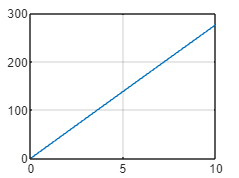

plot(X,Y(:,3))
% axis([0 1000 0 1000])
grid

% legend(string(Subs))